**Question One: **Bifurcations and Periodic Orbits for the Logistic Map


$$f_a(x) = ax(1-x)$$


%initialize logistic model

syms a x;
f = a*x*(1-x)
fixedPoints = solve(f-x,x)

***Part A: ****use derivative criteria to determine the bifurcation value *$a_1$* for which *$f_a \left(x\right)$* undergoes a period doubling bifurcation that creates a period-2 orbit*

**Solution: **

    Per Theorem 11.1 (ASY) a period doubling bifurcation must satisfy the following:

- 
$$\frac{\partial f}{\partial a}(\bar a, \bar x) \neq 0
$$


- 
$$\frac{\partial f}{\partial x}(\bar a, \bar x) = -1$$


- 
$$\frac{\partial ^2 f}{\partial x^2} (\bar a, \bar x)\neq 0$$


To determine $a_1$, we compute the partial derivatives and compute their value at the fixed points:

%evaluate partial derivatives:
partialFa = diff(f,a);
partialFx = diff(f,x);
partialFxx = diff(partialFx,x);

%evaluate partial derivatives at fixed points where x1 = 0
x = fixedPoints(1)
pFa_x1 = subs(partialFa)
pFx_x1 = subs(partialFx)
pFxx_x1 = subs(partialFxx)

**Interpretations:**

- At $x_1 = 0$, $\frac{\partial f}{\partial a} = 0$. This violates condition #2 and implies that a period doubling bifurcation does not occur for any value of $a$ at $x_1 = 0$.

- For $a=1$, $\frac{\partial f}{\partial x}(1, 0) = +1$, $\frac{\partial ^2 f}{\partial x^2} (1, 0)= -2 $ and satisfies the criteria for a transcritical/pitchfork bifurcation according to Theorem 11.10 in ASY 

We proceed to evaluate the values of the partial derivatives at $x_2 =\frac{a-1}{a}$

%evaluate partial derivatives at fixed points where x2 = (a-1)/a
x = fixedPoints(2)
pFa_x2 = subs(partialFa);
pFx_x2 = subs(partialFx);
pFxx_x2 = subs(partialFxx);

To determine the values of $a_1$ at which the $\frac{\partial f}{\partial x}(\bar a, \bar x) = -1$ we compute the following: 

%find bifurcation value a1 when pFx_x2 = -1
a1 = solve(pFx_x2 +1)
x2 = (a1-1)/a1

Now we check the conditions for a period doubling bifurcation:

a = a1;
pFa_PD = subs(pFa_x2)
pFx_PD = subs(pFx_x2)
pFxx_PD = subs(pFxx_x2)

**Interpretation: **Note that at $(\bar a_1, \bar x_2) = \left(3, \frac{2}{3} \right)$, all three conditions for the period doubling bifucation are satisfied. 

- 
$$\frac{\partial f}{\partial a}(\bar a_1, \bar x_2) = \frac{2}{9}  $$


- 
$$\frac{\partial f}{\partial x}(\bar a_1, \bar x_2) = -1$$


- 
$$\frac{\partial ^2 f}{\partial x^2} (\bar a_1, \bar x_2) = -6$$


We conclude that  $f_a \left(x\right)$ has a period doubling bifurcation at $(\bar a_1, \bar x_2) = \left(3, \frac{2}{3} \right)$. The bifurcation diagram is shown below:

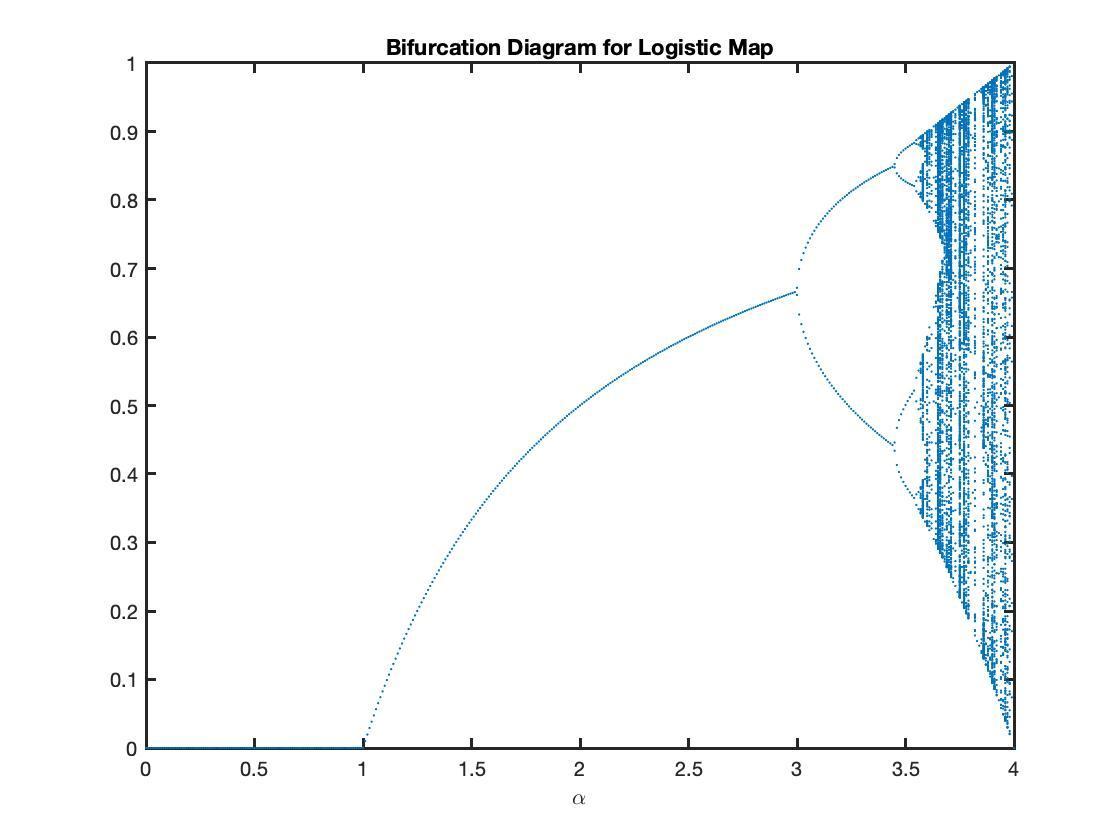

***Part B: ****Form *$g_a(x)=f(f_a(x))$* and determine the bifurcation *$g_a(x)$*undergoes when *$a=a_1$*as found in Part A. *

**Solution:**

In order to determine the bifucation the system $g_a(x)$ undergoes at $a=3$, we subsitute in $a$,  compute $g_a(x)$ and determine the fixed points for the system.

syms x;
f = 3*x*(1-x)
g = expand(3*f*(1-f))
fixedPointsG = solve(g-x, x);

We note that $g_3(x)$ has  two distinct roots at $a=3$, $x=0$ with multiplicity 1 and $x=\frac{2}{3}$ with multiplicity 3. To determine the bifurcation at the fixed points, we evaluate the partial derivatives at $(\bar a, \bar x_1) = (3,0)$ 

%problem set up
syms a;
f = a*x*(1-x);
g = expand(a*f*(1-f));

%compute partial derivatives
pG_a = diff(g,a);
pG_x = diff(g,x);
pG_xx = diff(pG_x,x);

%evaluate partial derivatives at x=0
x = fixedPointsG(1)
pG_a1 = subs(pG_a);
pG_x1 = subs(pG_x)
pG_xx1 = subs(pG_xx);

%evaluate partial derivatives at a=3
a=3
pG_a1solved = subs(pG_a1)
pG_x1solved = subs(pG_x1)
pG_xx1solved = subs(pG_xx1)

**Interpretation:  **Note that at $(\bar a, \bar x_1) = (3,0)$  

- 
$$\frac{\partial g}{\partial a}(\bar a_1, \bar x_1) = 0  $$


- 
$$\frac{\partial g}{\partial x}(\bar a_1, \bar x_1) = 9$$


- 
$$\frac{\partial ^2 g}{\partial x^2} (\bar a_1, \bar x_1) = -72$$


and $g_a \left(x\right)$ does not satisfy the criteria for either a saddle node, pitchfork, transcritical, or period doubling bifurcation. Upon closer inspection of $\frac{\partial g}{\partial x}\left(a,0\right)$, it is evident that the only bifurcation of the four that could occur at this this point is a pitchfork/transcritical bifurcation if $a=1$. 

We proceed to evaluate the partial derivatives of $g_a \left(x\right)\;\mathrm{at}\;$$(\bar a_1, \bar x_2) = \left(3,\frac{2}{3} \right)$

%evaluate partial derivatives at x=2/3
x = fixedPointsG(2)
pG_a2 = subs(pG_a);
pG_x2 = subs(pG_x)
pG_xx2 = subs(pG_xx);

%evaluate partial derivatives at a=3
a=3
pG_a1solved = subs(pG_a2)
pG_x1solved = subs(pG_x2)
pG_xx1solved = subs(pG_xx2)

**Interpretation:  **Note that at $(\bar a_1, \bar x_2) = \left(3,\frac{2}{3}\right)$  

- 
$$\frac{\partial g}{\partial a}(\bar a_1, \bar x_2) = 0  $$


- 
$$\frac{\partial g}{\partial x}(\bar a_1, \bar x_2) = 1$$


- 
$$\frac{\partial ^2 g}{\partial x^2} (\bar a_1, \bar x_2) = 0$$


Thus $g_a \left(x\right)$ does not satisfy the criteria for either a saddle node, pitchfork, transcritical, or period doubling bifurcation. 

However, bifurcation diagram for $g_a \left(x\right)$ does demonstrate *something *at $(\bar a_1, \bar x_2) = \left(3,\frac{2}{3}\right)$

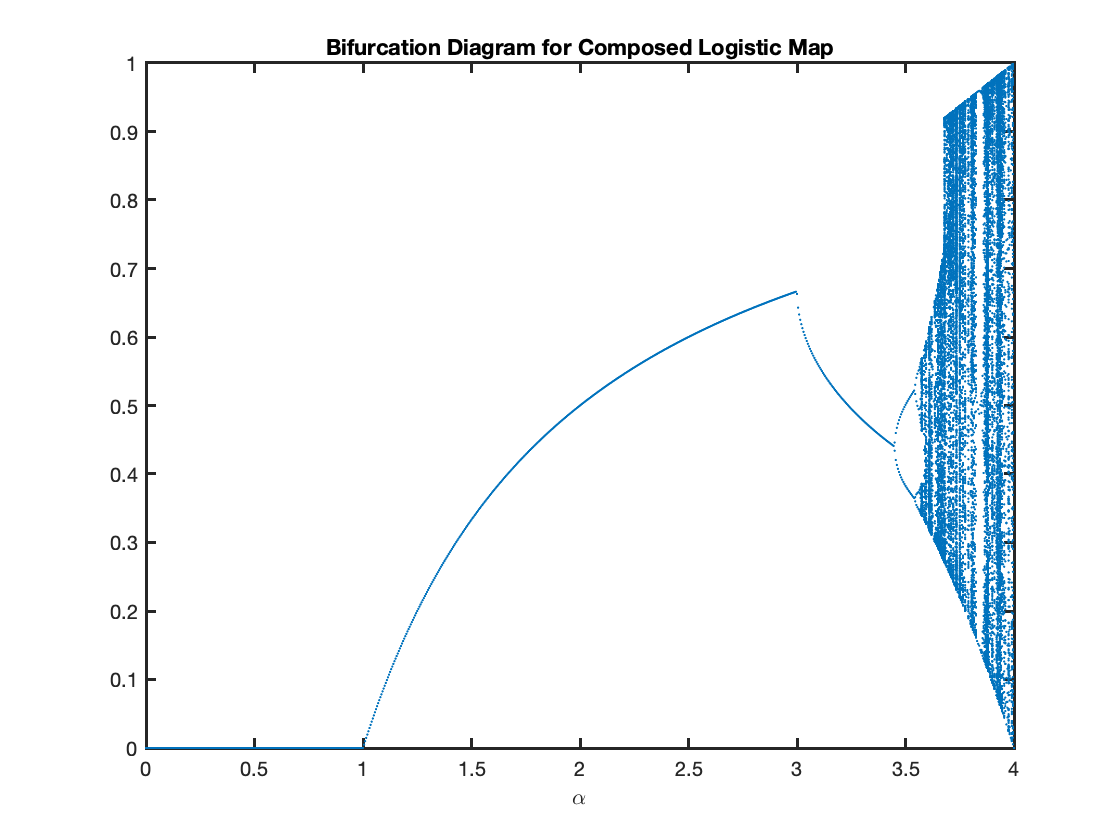

***Part C. ****Identify the value *$a_2$* at which *$g_a \left(x\right)$* undergoes a period doubling bifurcation.*

    Per Theorem 11.1 (ASY) a period doubling bifurcation must satisfy the following:

- 
$$\frac{\partial f}{\partial a}(\bar a, \bar x) \neq 0
$$


- 
$$\frac{\partial f}{\partial x}(\bar a, \bar x) = -1$$


- 
$$\frac{\partial ^2 f}{\partial x^2} (\bar a, \bar x)\neq 0$$


To determine $a_2$, we determine the fixed points for $g_a \left(x\right)$

%initialize problem
syms a x;
f = a*x*(1-x)
g = expand(a*f*(1-f))
fixedG = solve(g-x, x)

%determine conditions for pG_x =-1
x= fixedG(1);
pG_x1 = subs(pG_x);
b1 = solve(pG_x1 +1,a)

x= fixedG(2);
pG_x2 = subs(pG_x);
b2 = solve(pG_x2 +1,a)

x= fixedG(3)
pG_x3 = subs(pG_x);
b3 = solve(pG_x3 +1,a)

x= fixedG(4)
pG_x4 = subs(pG_x);
b4 = solve(pG_x4 +1,a)

**Interpretation:  **We discard the bifurcation values for $b_1 ,b_2$ because they are complex valued. Note that $b_3 =b_4$. We proceed to evaluate the partial derivatives of $g_a \left(x\right)$ at $b_{31} ,b_{32}$ to determine if a period doubling bifurcation occurs at either point. 

%determine fixed point values:
x= fixedG(3)
 
pG_a_FP1 = subs(pG_a)
pG_x_FP1 = subs(pG_x)
pG_xx_FP1 = subs(pG_xx)

a= b3(1)
pG_a1Solved = double(subs(pG_a_FP1))
pG_x1Solved = double(subs(pG_x_FP1))
pG_xx1Solved = double(subs(pG_xx_FP1))
FP1 = double(subs(x))

a= b3(2)
pG_a2Solved = double(subs(pG_a_FP1))
pG_x2olved = double(subs(pG_x_FP1))
pG_xx2Solved = double(subs(pG_xx_FP1))
FP2 = double(subs(x))

We proceed to evaluate the partial derivatives of $g_a \left(x\right)$ at $b_{41} ,b_{42}$ to determine if a period doubling bifurcation occurs at either point. 

x= fixedG(4)
 
pG_a_FP2 = subs(pG_a);
pG_x_FP2 = subs(pG_x);
pG_xx_FP2 = subs(pG_xx);

a= b4(1)
pG_a3Solved = double(subs(pG_a_FP2))
pG_x3Solved = double(subs(pG_x_FP2))
pG_xx3Solved = double(subs(pG_xx_FP2))
FP3 = double(subs(x))

a= b4(2)
pG_a4Solved = double(subs(pG_a_FP2))
pG_x4Solved = double(subs(pG_x_FP2))
pG_xx4Solved = double(subs(pG_xx_FP2))
FP4 = double(subs(x))

**Interpretation: **Our analysis reveals that $g_a \left(x\right)$ has four period doubling bifurcations at four different fixed points. Of particular interest and most surprising in this analysis is the existence of period doubling bifurcations from $a\in \left(-4,0\right)$ shown below:

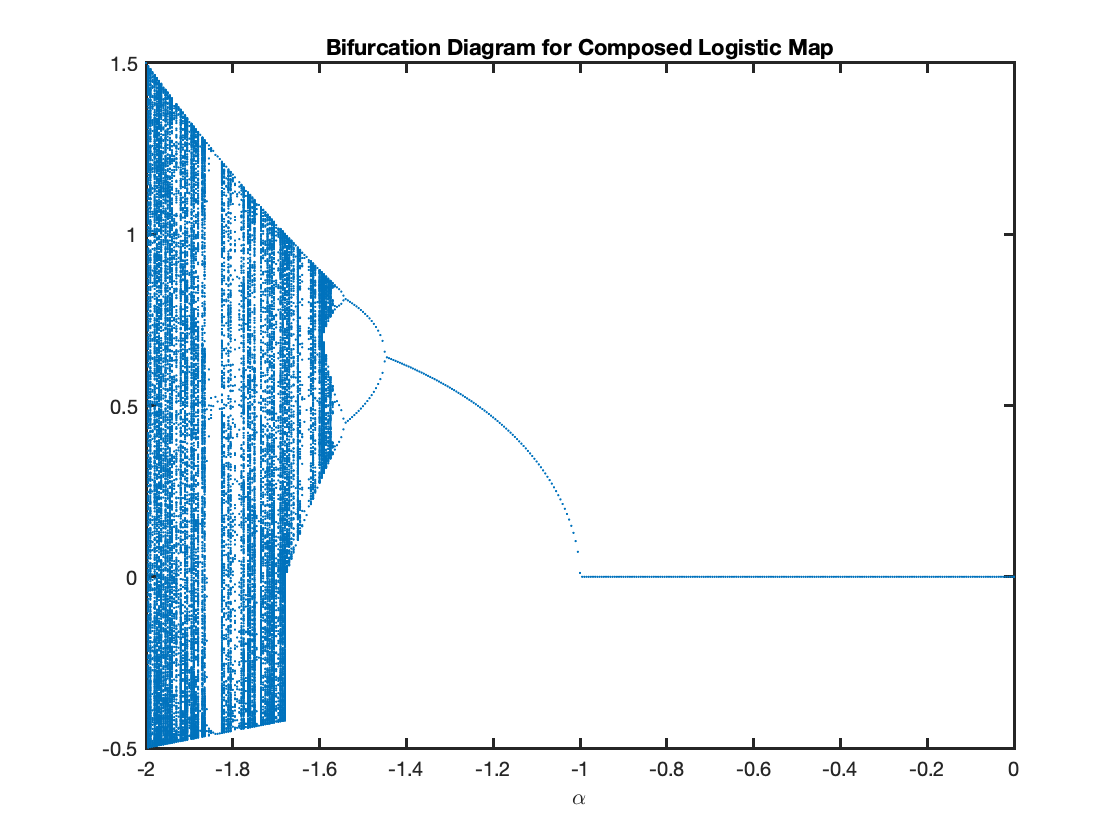

**Part D. ***What type of orbit does *$f_a \left(x\right)$ have at $a_2$?

$f_a \left(x\right)$ has a period four orbit when $g_a \left(x\right)$ has a period doubling orbit. 